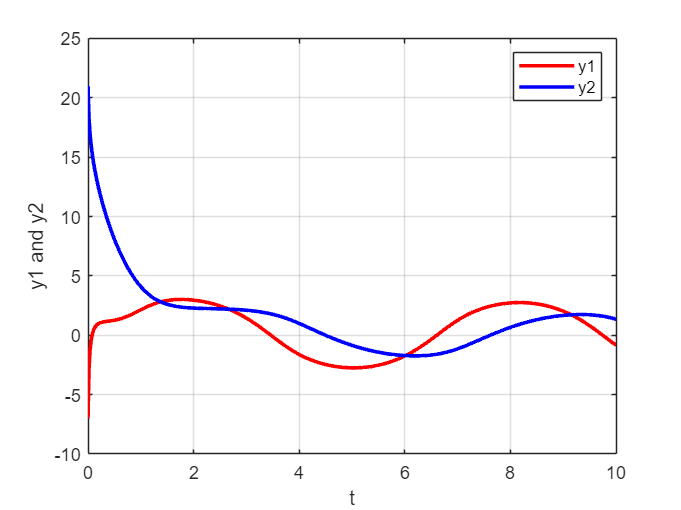

%% 初始设置
close all,clear,clc,
tic,    %启动秒程序运行时间计时
% 初始化仿真时间区间
t0 = 0.0;
tf = 10.0;
%步长
t_step = 0.0001;

tout = t0:t_step:tf;

len = length(tout);

x1 = zeros(len, 1);
x2 = zeros(len, 1);
y1out = zeros(len, 1);
y2out = zeros(len, 1);

%初始条件
x10 = 5;
x20 = -6;
x1(1) = x10;
x2(1) = x20;
y1out(1) = x1(1) + 2*x2(1);
y2out(1) = 3*x1(1) - x2(1);
%% 仿真
%迭代求解
for t = 1:len-1
    x2dot = -x1(t) - 3*x2(t) - x2(t)*x2(t)*x2(t) + 5*sin(tout(t));
    x1dot = -x1(t) + x2(t);
    x1(t+1) = x1(t) + x1dot * t_step;
    x2(t+1) = x2(t) + x2dot * t_step;
    y1out(t+1) = x1(t+1) + 2*x2(t+1);
    y2out(t+1) = 3*x1(t+1) - x2(t+1);
end

%% 绘图
%画图1
figure(1);
plot(tout, y1out, "r", tout, y2out, "b", 'LineWidth', 2);
ylabel('y1 and y2');
xlabel('t');
grid on;
legend("y1","y2");

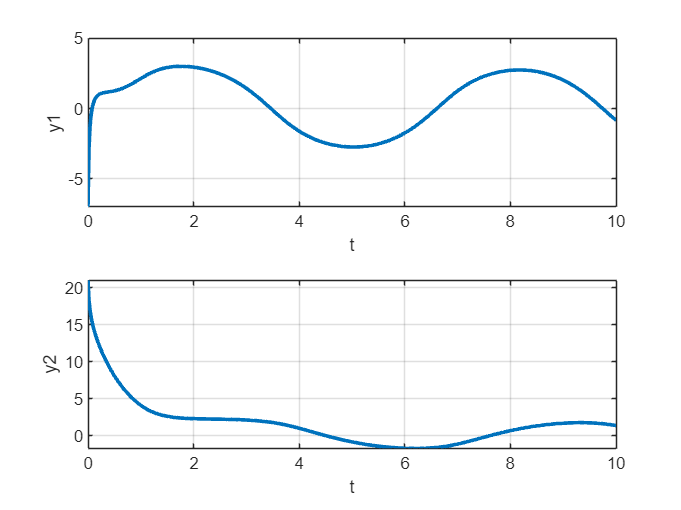


%画图2
figure(2);
subplot(2,1,1);
plot(tout, y1out, 'LineWidth', 2);
ylabel('y1');
xlabel('t');
grid on;

subplot(2,1,2);
plot(tout, y2out, 'LineWidth', 2);
ylabel('y2');
xlabel('t');
grid on;


toc %输出运行时间

历时 1.139982 秒。
